%#ok<*CLALL>

clear all;clc 


% Load data set data_20250902_1358_0.30L_0.15R
data = readtable('data/data_20250902_1358_0.30L_0.15R.csv', 'NumHeaderLines', 1);
data = table2array(data);
data(:,2:3)= data(:,2:3)/1000;
% Test run the extended Kalman Filter.
L = 0.1512;
v_l = 0.3;
v_r = 0.15;
u = [v_l; v_r];
V = (v_r+v_l)/2;
w = (v_r-v_l)/L;
T = 0.01;
% Heuristics Based selection of Q
sigma_xy = V*T;
sigma_theta = abs(w)*T*3;

Q = diag([sigma_xy^2,sigma_xy^2,sigma_theta^2]);
R = diag([0.002^2,0.002^2]); % based on Qualsys camera system specifications.
theta_0 = 3*pi/2; % initial angle (from plot)
x_0 = [data(1, 2:3).'; theta_0]; 
ekf = lab1EKF(x_0, Q, R, T); 
estimates = zeros(size(data, 1), 3); 
P_history = {};
P_trace = zeros(length(data),1);
NIS = 0;
det_p = 0;
for k = 1:size(data, 1)
    if k>1
        ekf.T = data(k,1) - data(k-1,1);
    end
    z = data(k, 2:3).'; 
    [x_current, P_current] = ekf.update(u, z);
    estimates(k, :) = x_current ;
    P_history{k}=P_current;
end



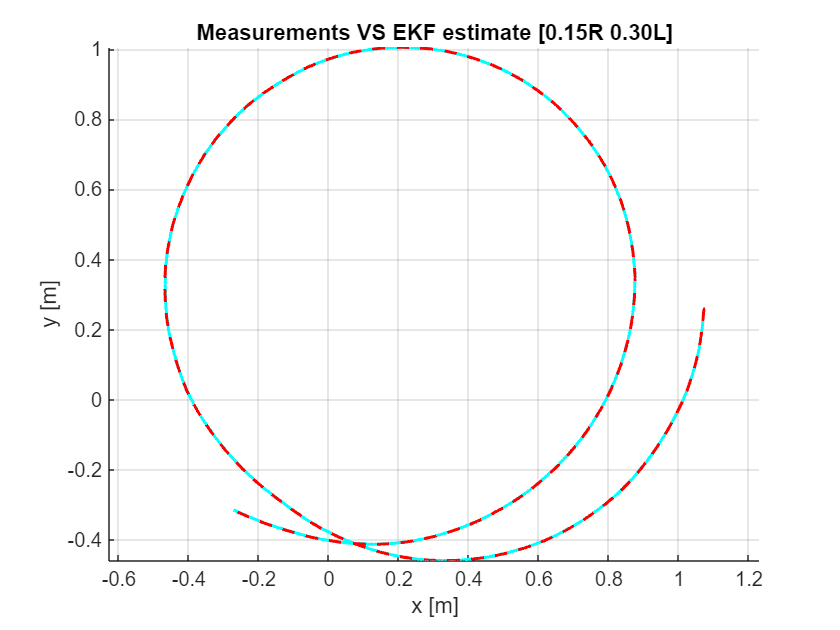

% Plot estimates. 
clf(); 
hold on; 
plot(estimates(:, 1), estimates(:, 2),'c',LineWidth=1.5);
plot(data(:, 2), data(:, 3),'r--',LineWidth=1.5);
xlabel('x [m]');
ylabel('y [m]');
title('Measurements VS EKF estimate [0.15R 0.30L]');
axis equal;
grid on;
hold off; 

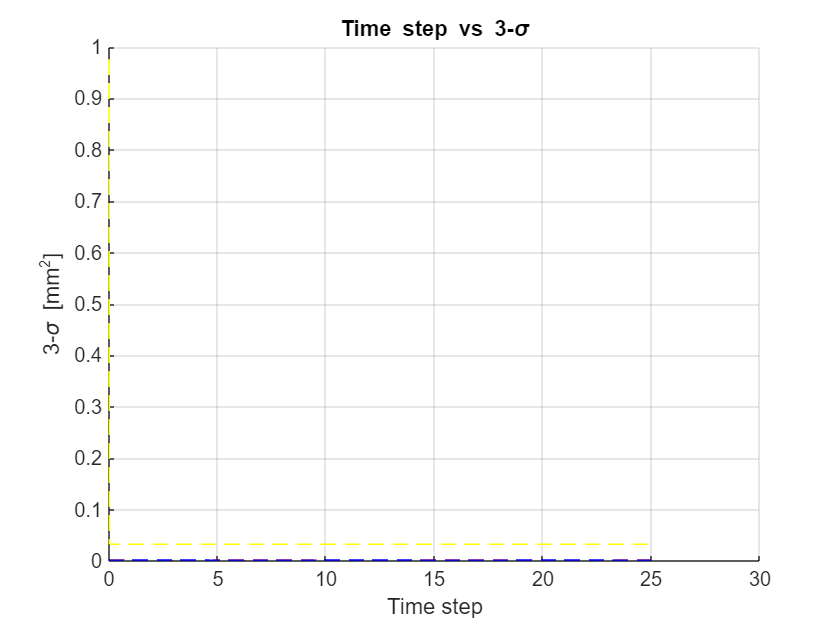


sigma_3 = zeros(length(data),3);

for k = 1:length(data)
    for i=1:3
        sigma_3(k,i) = sqrt(P_history{k}(i,i));
    end
end

clf()
figure;hold on;
plot(data(:,1),sigma_3(:,1),'r--');
plot(data(:,1),sigma_3(:,2),'b--');
plot(data(:,1),sigma_3(:,3),'y--');
xlabel('Time step'); ylabel('3-\sigma [mm^2]');
title('Time step vs 3-\sigma');
grid on;
hold off;

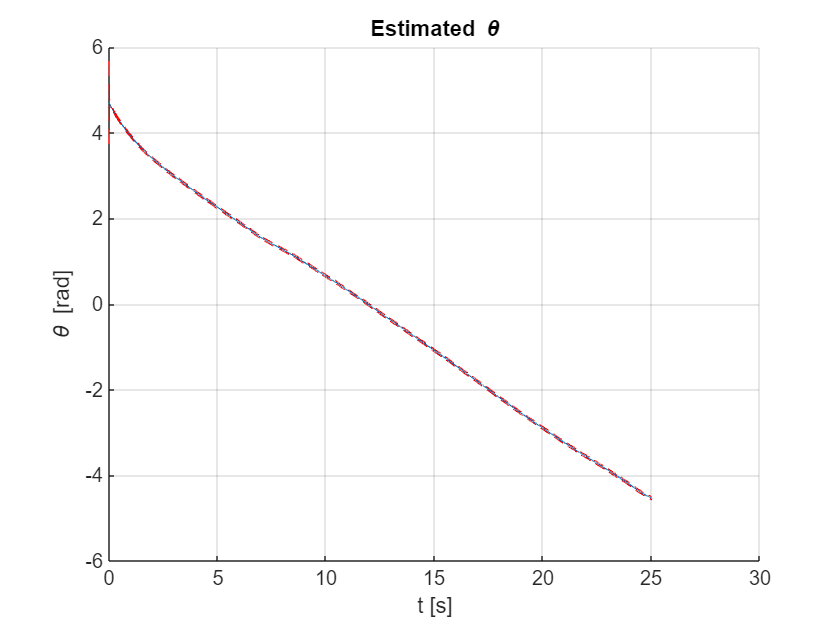

figure; hold on;
plot(data(:,1), estimates(:, 3))
plot(data(:,1), estimates(:, 3)+sigma_3(:,3),'r--')
plot(data(:,1), estimates(:, 3)-sigma_3(:,3),'r--')
xlabel('t [s]');
ylabel('\theta [rad]');
title('Estimated \theta');
%legend('raw data', 'estimate', 'location', 'best')
grid on;
hold off;